# Homework 1 (50pt)

*Type your NAME (first, last) and ID below*

Boxuan Zhang 95535906

## Homework instructions:

- Write your **name** and **student ID** in the above section.

- Make sure you have downloaded all related files from Canvas.

- Write ALL answers and your MATLAB code in **THIS** livescript file, make sure you write your code in the **code block** and test it before submission.

- Usually you should only submit this livescript (.mlx file) with all your answers and code. However, if you have additional .m files, please make sure to put them in the same folder.  

- Rename this livescript as "***Math9_HW1_(your name)_(your ID).mlx***" before submission!

- You are responsible for checking UCI email and course Canvas page regularly for potential updates.

**Note:** Throughout this homework, please do not create arrays by entering all individual element values manually using enumeration, nor use control flows (e.g. if-else or loops that we will learn later in this quarter). 

## Problem 1. Schemes of Numerical Differentiation (12pt)

To approximate the derivative $f^{\prime } \left(x\right)$ at certain point $x$, in numerical analysis people have designed many different schemes. For example, given a small positive number $h$, we have:

- Forward scheme, $\frac{f(x+h)-f(x)}{h}$

- Backward scheme,  $\frac{f(x)-f(x-h)}{h}$

- Central scheme, $\frac{f(x+h)-f(x-h)}{2h}$

For $f\left(x\right)=e^{-x^2 } \cos \left(x\right)$, please follow the instructions below to find its numerical derivative using different schemes:

**(1pt) **1. Derive the derivative function$f^{\prime } \left(x\right)$ (what you did in Math 2A, not the definition of the derivative) and type it below using the "**Insert -- Equation**" function (you can either use equation editor or Latex): 

*(for example: if *$f\left(x\right)=2x$, you should type $f^{\prime } \left(x\right)=2$ below*)*

 
$$f^{\prime } \left(x\right)=-2xe^{-x^2 } \cos \left(x\right)-e^{-x^2 } \sin \left(x\right)$$


**(2pt = 1pt + 1pt) **2. In the code block below, insert two **Numerical Sliders**, to adjust the values of: 1) the variable $h$, from range ${10}^{-4}$ to  ${10}^{-2}$, with the step ${10}^{-4}$; 2) the variable $x$, from range $1$ to $10$, with the step $0\ldotp 1$. (*Please use numerical sliders here even if you know how to do it with the command*)

h = 0.001;
x = 1;

**(1pt) **3. Define the variable named "`der"` to represent the derivative function $f^{\prime } \left(x\right)$. 

der = -2*x*(exp(1)^(-x^2))*cos(x) - (exp(1)^(-x^2)*sin(x))

der =   -0.707092096345938


**(3pt) **4. Using three schemes above, assign three variables named "`der_appr_fw", "der_appr_bw", "der_appr_c"`, with the forward, backward and central numercial derivative respectively. 

der_appr_fw = (exp(1)^(-(x+h)^2) * cos(x+h) - exp(1)^(-x^2)*cos(x)) / h

der_appr_fw =   -0.706373520795139


der_appr_bw = (exp(1)^(-x^2)*cos(x) - exp(1)^(-(x-h)^2) * cos(x-h)) / h

der_appr_bw =   -0.707810525275576


der_appr_c = (exp(1)^(-(x+h)^2) * cos(x+h) - exp(1)^(-(x-h)^2) * cos(x-h)) / (2*h)

der_appr_c =   -0.707092023035358


**(3pt) **5. Define three variables named` "rel_err_fw", "rel_err_bw", "rel_err_c"` as the relative error of three schemes. Here is the general definition of relative error: $\frac{\left|E-A\right|}{E}$ , where $A$ denotes the approximated value, $E$ denotes the real value, and $\left|\;\right|$denotes absolute value.

rel_err_fw = abs(der - der_appr_fw) / der

rel_err_fw =   -0.001016240394303


rel_err_bw = abs(der - der_appr_bw) / der

rel_err_bw =   -0.001016033036362


rel_err_c = abs(der - der_appr_c) / der

rel_err_c =     -1.036789701976823e-07


**hint1:** using the "`abs"` function in MATLAB. 

**hint2:** the variable "`der"` representing the derivative function should be the "real value".

In your code, please suppress the output for step 2-4, and only allow to show the output for step 5.  Now drag the slider bars, and explore the following two questions:

**(1pt) **1) With the change of `h`, how will the approximation effect change for all three schemes (just report the qualitative trend is enough)?

**(1pt) **2) Which sheme tends to have the best approxiamtion in terms of relative error?

You don't need to record and report the exploration process, but instead write your observation below, using italic font.

***1）With H increasing, forward scheme and central scheme increase, backward scheme decreases.***

***2）The central scheme is the best approximation, because it has few changes with the change of x and h.***

## Problem 2. Visualize the 3D earth (6pt)

Please follow the instructions below:

**(1pt) **1. Insert a section break before this section title "Problem 2: Visualize the 3D earth".

**(1pt) **2. Change the format of this section title to "Head 1".

**(4pt = 1pt + 1pt + 1pt +1pt) **3. Insert the code block below and write commands in livescript to do the following: 

3.1) load the variables in *h1_data.mat* (please download it from Canvas); 

3.2) copy-paste all the commands in script *plot_earth.m* (please download it from Canvas); 

3.3) Run this section, and you should see the 3D earth as embedded figure. Rotate the earth to the angle where North America directly face you (don't have to be exact); 

3.4) After you rorate, you should see the "update code" suggestion in livescript. Follow the suggestion (you will see the change in your code) and re-run this section.

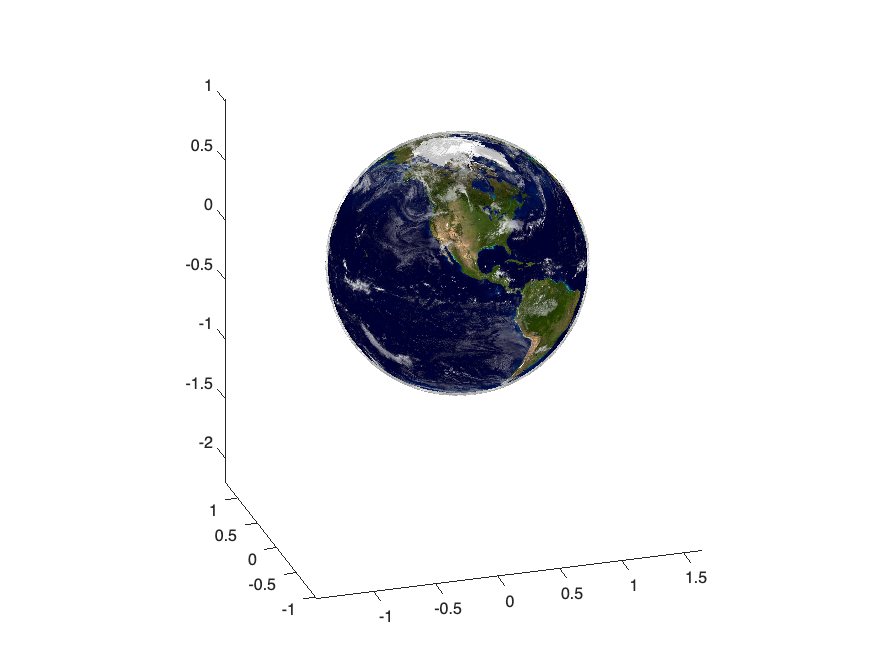

load("hw1_data.mat")
[px,py,pz] = sphere(50);                % generate coordinates for a 50 x 50 sphere
sEarth = surf(px, py ,flip(pz));
sEarth.FaceColor = 'texturemap';        % set color to texture mapping
sEarth.EdgeColor = 'none';              % remove surface edge color
sEarth.CData = earth;    
hold on
sCloud = surf(px*1.02,py*1.02,flip(pz)*1.02); 
sCloud.FaceColor = 'texturemap';        % set color to texture mapping
sCloud.EdgeColor = 'none';              % remove surface edge color
sCloud.CData = clouds;                  % set color data 
sCloud.FaceAlpha = 'texturemap';        % set transparency to texture mapping
sCloud.AlphaData = max(clouds,[],3);  % set transparency data 
hold off

daspect([1 1 1])
grid off

xlim([-1.46 1.66])
ylim([-1.02 1.33])
zlim([-2.20 1.02])
view([342.60 23.53])

## Problem 3. Array Creation (10pt)

Insert the code blocks below in this section to create and output following arrays. When creating the arrays, you are free to define as many intermediate variables as you like, but please suppress their output. The output should only show the final arrays created.

**(2pt) **1. Row vector v = $\left\lbrack \begin{array}{cccccccccc}
-3 & 13 & -23 & 33 & -43 & 53 & \ldotp \ldotp \ldotp  & -1203 & 1213 & -1223
\end{array}\right\rbrack$.

**(4pt) **2. Row vector v = $\left\lbrack \begin{array}{cccccccccc}
100 & 99\;\;\ldotp \ldotp \ldotp  & 2 & 1 & 0 & 1\;\;2 & \ldotp \ldotp \ldotp  & 99 &  & 100
\end{array}\right\rbrack$. Please use two different ways to make this vector.

**(4pt) **3. Matrix $A$ with the structure $\left\lbrack \begin{array}{cc}
0 & \mathrm{v}\\
{\mathrm{v}}^T  & B
\end{array}\right\rbrack$, where $0$ is a number (1x1 size), $B$ is a 5-by-5 matrix with all elements equal to 4, $\mathrm{v}$ is a vector in which all the elements are 1, and $\mathrm{v}$ should be generated by the MATLAB code, not by entering the elements manually. Here ${\mathrm{v}}^T$ means the transpose of $\mathrm{v}$. 

% 1
v = 3:10:1223;
u = -v(1:2:end);
v(1:2:end) = u;
v

v =     -3    13   -23    33   -43    53   -63    73   -83    93  -103   113  -123   133  -143   153  -163   173  -183   193  -203   213  -223   233  -243   253  -263   273  -283   293  -303   313  -323   333  -343   353  -363   373  -383   393  -403   413  -423   433  -443   453  -463   473  -483   493


% 2 method 1
v1 = -100:1:100;
abs(v1)

ans =    100    99    98    97    96    95    94    93    92    91    90    89    88    87    86    85    84    83    82    81    80    79    78    77    76    75    74    73    72    71    70    69    68    67    66    65    64    63    62    61    60    59    58    57    56    55    54    53    52    51


% 2 method 2
v = [linspace(100,1,100), 0, linspace(1,100,100)]

v =    100    99    98    97    96    95    94    93    92    91    90    89    88    87    86    85    84    83    82    81    80    79    78    77    76    75    74    73    72    71    70    69    68    67    66    65    64    63    62    61    60    59    58    57    56    55    54    53    52    51


% 3
B = ones(5)*4;
v = ones(1,5);
A = [[0 v]; [v' B]]

A =      0     1     1     1     1     1
     1     4     4     4     4     4
     1     4     4     4     4     4
     1     4     4     4     4     4
     1     4     4     4     4     4
     1     4     4     4     4     4


## Problem 4. Parameterized Curve Plotting (10pt)

Follow the examples in lecture and insert code blocks below in this section to plot the following curves. You are free to create the array of parameter $t$, but make sure the range is correct, and the array contains at least 1,000 elements.

**(5pt) **1. $\left\lbrace \begin{array}{ll}
x\left(t\right)=\sin \left(t\right)\cos \left(t\right)\log \left|t\right| & \\
y\left(t\right)={\left|t\right|}^{\frac{1}{3}} {\left(\cos \left(t\right)\right)}^{\frac{2}{3}}  & 
\end{array}\right.$,  $-1\le t\le 1$ (here $\left|t\right|$ means absolute value of t)

**(5pt) **2. $\left\lbrace \begin{array}{ll}
x\left(t\right)=\cos \left(t\right)+t^2 \sin \left(t\right) & \\
y\left(t\right)=\sin \left(t\right)-t^2 \cos \left(t\right) & 
\end{array}\right.$, $-20\le t\le 20$

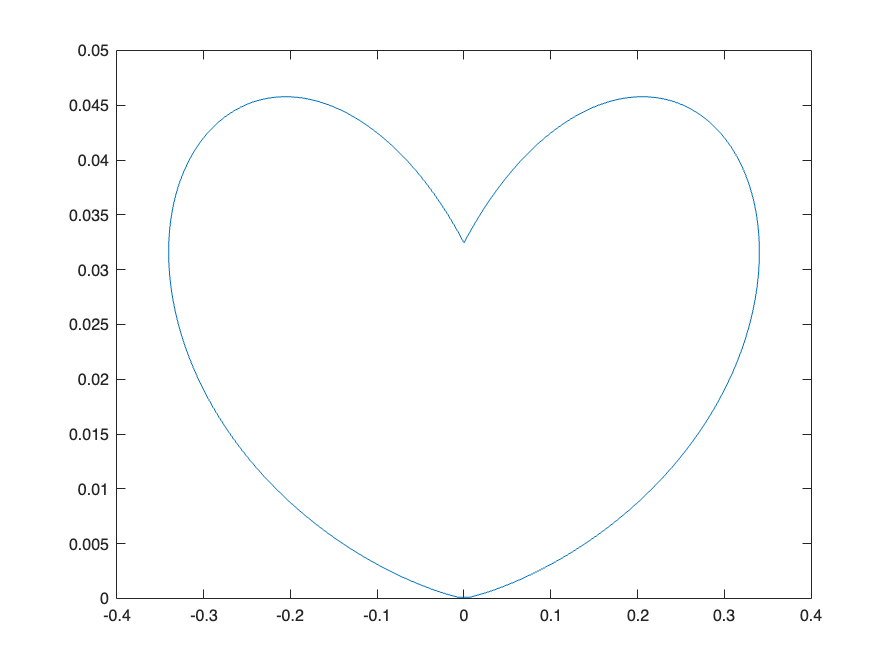

% start to write your code below
t = linspace(-1,1,1000);
x = sin(t).*cos(t).*log(abs(t));
y = (abs(t).^1/3).*(cos(t).^2/3);
plot(x,y)

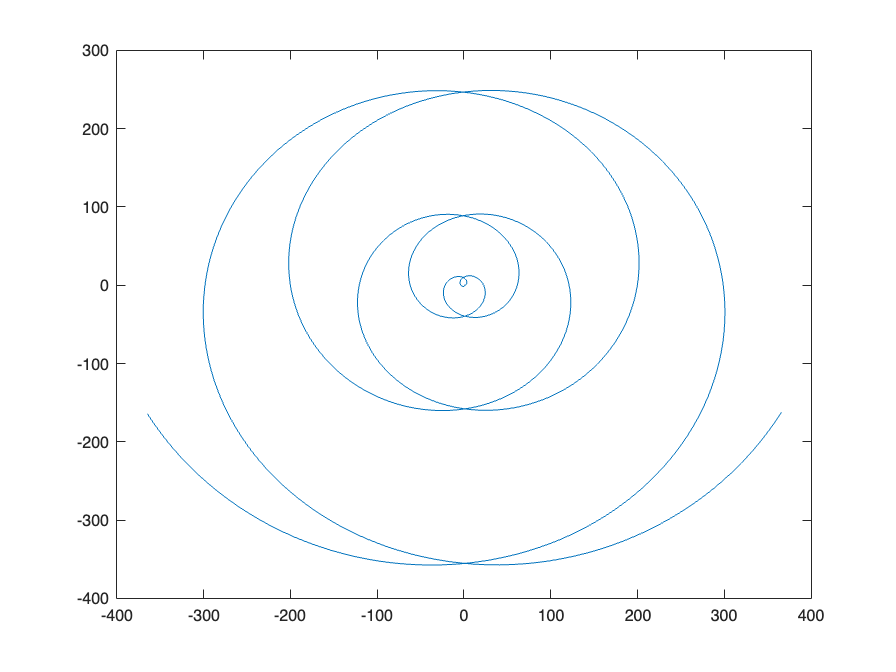

t1 = linspace(-20,20,1000);
x1 = cos(t1) + t1.^2 .* sin(t1);
y2 = sin(t1) - t1.^2 .* cos(t1);
plot(x1,y2);

## Problem 5. Numerical Integral (12pt)

Recall the numerical integral we discussed in the lecture. For the evenly-spaced partition of interval $\left\lbrack a,b\right\rbrack$, we denote the points as $a=x_0 <x_1 <\ldotp \ldotp \ldotp <x_{n-1} <x_n =b$ and step size $h=\frac{b-a}{n}={x_i -x}_{i-1}$ . Beyond end-point formulas, people have also developed the following two formulas to approximate the integral value of $\int_a^b f\left(x\right)\textrm{dx}$:

**Mid-point formula:** $h\sum_{i=1}^n f\left(\frac{x_{i-1} +x_i }{2}\right)$

**Trapezoidal formula:** $h\sum_{i=1}^n \frac{f\left(x_{i-1} \right)+f\left(x_i \right)}{2}=h\left(\frac{f\left(x_0 \right)+f\left(x_n \right)}{2}+f\left(x_1 \right)+f\left(x_2 \right)+\ldotp \ldotp \ldotp +f\left(x_{n-1} \right)\right)$

***hint1:**** a convenient way to implement mid-point formula is to generate the arrays of midpoints *$\frac{x_0 +x_1 }{2}$, $\frac{x_1 +x_2 }{2}$, $\frac{x_2 +x_3 }{2}$, ...*, and then apply the function to midpoint array and get the sum.*

***hint2:*** $f\left(\frac{x_{i-1} +x_i }{2}\right)$ and $\frac{f\left(x_{i-1} \right)+f\left(x_i \right)}{2}$ are not the same.

Please write code below to implement the two formulas respectively, approximating $\int_{10}^{20} \left(e^{-x} +e^{-x^2 } \right)\textrm{dx}$  with $h={10}^{-2}$.

As the reference, here is the approximation integral value calculated by built-in function of Matlab. In principle, your results should be similar to this value.

format long
integral(@(x)(exp(-x) + exp(-x.^2)),10,20)

ans =      4.539786860886243e-05


% continue your codes below
h = 10e-2;
a = 10;
b = 20;
x = a:h:b;
% mid-point integral
f = @(x) exp(-x) + exp(-x.^2);
mid_point = (x(1:end-1) + x(2:end)) / 2;
mid_integral = h*sum(f(mid_point))

mid_integral =      4.537895834592351e-05


% trapezoidal integral
trap1 = (f(x(1))+f(x(end))) / 2;
trap2 = sum(f(x(2:end-1)));
trap_integral1 = h*(trap1 + trap2)

trap_integral1 =      4.543569386227781e-05


## **Reference and Acknowledgement**

*You may list all the materials you referred to (including online materials and papers) and acknowledge the people who helped you in this section.*

## **Other Comments (optional)**

*You are welcome to leave your course-related comments here (lecture, homework, discussion session, etc.), you can also leave your comments in the Ed discussion panel or via email.*